#### Simple constant elasticity of substitution example:


$$f(x_1,x_2) = (x_1^\rho+x_2^\rho)^{\frac{\theta}{\rho}

$$


#### Homogeneity/Returns to scale:

Change level of inputs by scalar $t$:


$$f(tx_1,tx_2)=((tx_1)^\rho+(tx_2)^\rho)^{\frac{\theta}{\rho}}=t^\theta f(x_1,x_2)

$$


Thus $f$ is homogenous of degree $\theta
$

if 

- $\theta = 1$ - homogenous of degree 1 = Constant returns to scale

- $\theta >1$ - homogenous of degree greater than 1 = Increasing returns to scale

- $\theta <1$ - homogenous of degree less than 1 = Decreasing returns to scale

Returns to scale refer to any ray (in the domain) from the origin. This example focusses on $x_1 = x_2$ (the top edge of the "side view" below)

#### Marginal rate of substitution

(exemplified by "view from above")

if 

- $\rho = 1$ mariginal rate of substitution is constant - perfect substitutes - Isoquants are straight lines - function is both (weakly) quasi-concave and quasi convex. $f()$ is a plane in 3D

- $\rho < 1$ - mariginal rate of substitution is diminishing - less than perfect substitutes - Isoquants are bowed to the origin - function is strictly quasi-concave ("better-than-sets" are convex sets). $f()$ is a "mountain" in 3D

- $\rho = 0$ - perfect compliments - Isoquants are L shaped (function limit used in example)

- $\rho > 1$ - mariginal rate of substitution is increasing - Isoquants are bowed away from the origin - function is strictly quasi-convex ("worse-than-sets" are convex sets). $f()$ is a "funnel" in 3D

Convexity/Concavity:

If $\theta, \rho < 1$, the function is globally concave

If $\theta, \rho > 1$, the function is globally convex

If they are on different sides of 1, the function is globally neither convex nor concave.



rho = 0.5;
theta = 1

n = 100;

theta = 0.5000

[X1,X2] = meshgrid(linspace(0,4,n))

if rho ~= 0

X1 =          0    0.0404    0.0808    0.1212    0.1616    0.2020    0.2424    0.2828    0.3232    0.3636    0.4040    0.4444    0.4848    0.5253    0.5657    0.6061    0.6465    0.6869    0.7273    0.7677    0.8081    0.8485    0.8889    0.9293    0.9697    1.0101    1.0505    1.0909    1.1313    1.1717    1.2121    1.2525    1.2929    1.3333    1.3737    1.4141    1.4545    1.4949    1.5354    1.5758    1.6162    1.6566    1.6970    1.7374    1.7778    1.8182    1.8586    1.8990    1.9394    1.9798
         0    0.0404    0.0808    0.1212    0.1616    0.2020    0.2424    0.2828    0.3232    0.3636    0.4040    0.4444    0.4848    0.5253    0.5657    0.6061    0.6465    0.6869    0.7273    0.7677    0.8081    0.8485    0.8889    0.9293    0.9697    1.0101    1.0505    1.0909    1.1313    1.1717    1.2121    1.2525    1.2929    1.3333    1.3737    1.4141    1.4545    1.4949    1.5354    1.5758    1.6162    1.6566    1.6970    1.7374    1.7778    1.8182    1.8586    1.8990    1.9394    

X2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    0.0404    

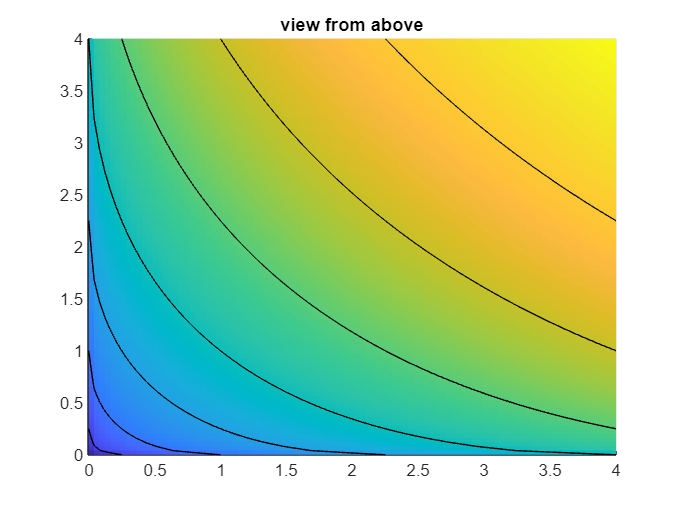

    Y = (X1.^rho + X2.^rho).^(theta/rho);
else
    Y = min(X1,X2).^theta
end

figure
hold on
surf(X1,X2,Y,'LineStyle','none')
contour3(X1,X2,Y,'k')
view(0,90)
title('view from above')
grid on

figure

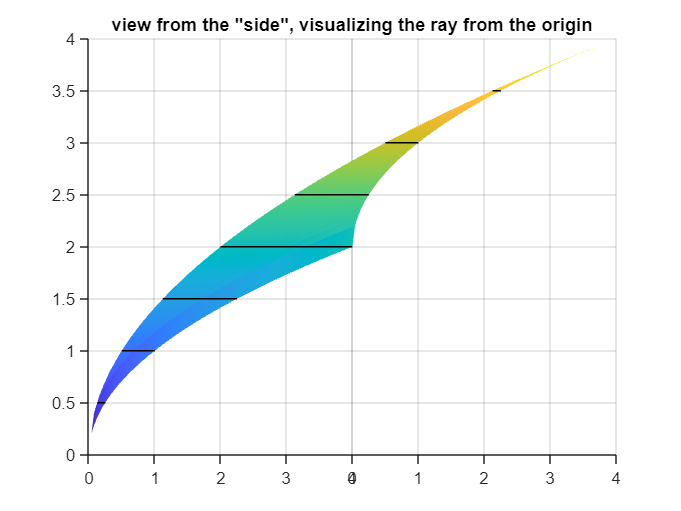

hold on
surf(X1,X2,Y,'LineStyle','none')
contour3(X1,X2,Y,'k')
view(45,0)
title('view from the "side", visualizing the ray from the origin')
grid on


Also pop out the figure and rotate in 3D